# Synergistic Hybrid Feedback for Robust Global Obstacle Avoidance

This MATLAB Live Script describes the implementation of the robust synergistic controller of the paper 

"Robust Hybrid Synergistic Feedback", P. Casau, R.G. Sanfelice, and C. Silvestre.

More specifically, its application to the global asymptotic stabilization of a setpoint on the plane in the presence of an obstacle. 

## Simulation of Hybrid Systems

*You will need to install the Hybrid Equations Toolbox to run this example.*

This is a self-contained live script in the sense that all the required functions to run this simulation are defined below. The controller and problem parameters are defined as global variables at the start.

global z_0 r Gamma_0 Gamma_1 theta_0 epsilon theta Gamma_2 k_u gamma hat_W
z_0   = [1 0]';            % Center of the obstacle
r     = 0.5;               % Radius of the obstacle
Gamma_0 = 2*eye(2);        % Nominal feedback gain
Gamma_1 = eye(2);          % Estimator gain
Gamma_2 = eye(2);          % Backstepping gain
k_u = 1;                   % Derivative gain
theta_0 = 1;               % Maximum disturbance magnitude 
epsilon = 1;               % Proj operator parameter
theta = sqrt(2)*[1 1]'./4; % Disturbance
gamma = 0.5;               % X_c: q'*x0 <= gamma 
hat_W = eye(2);            % Matched uncertainty - See Assumption 2

% Simulation parameters
TSPAN = [0 10];            % Continuous-time bounds
JSPAN = [0 10];            % Discrete-time bounds
rule  = 1;                 % Priority given to jumps
z_i   = [2;0];             % Initial position on the plane
q_i   = [0;-1];             % Initial controller variable
xi_0  = [psi(z_i) ;q_i];   % Initial condition


%Simulation of the nominal system
[t,j,xi] = HyEQsolver(@F_cl0, @G_cl0, @C_0, @D_0, xi_0, TSPAN, JSPAN, rule);

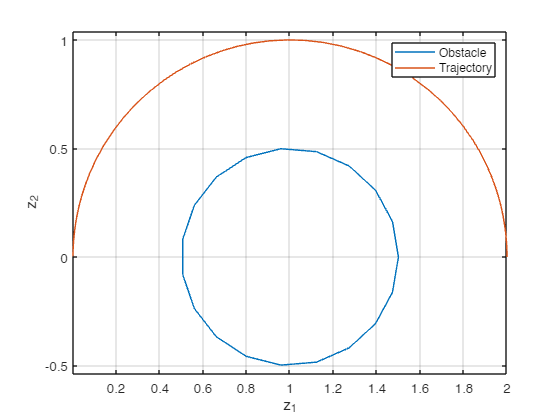

%Post-processing
x = xi(:,1:3);
q = xi(:,4:5);
z = planar_traj(x);
plot_planar_trajectory(z);

legend('Obstacle','Trajectory')

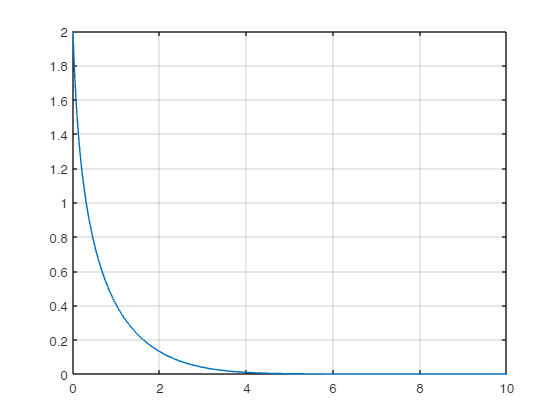

% Lyapunov function
plot(t, arrayfun(@(I) V_0(x(I,:)', q(I,:)'), (1:numel(t))'))
grid on

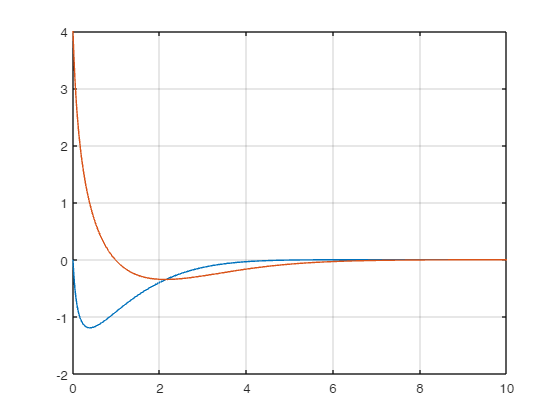


% Control inputs
u = cell2mat(arrayfun(@(I) kappa_0(x(I,:)', q(I,:)'), (1:numel(t)),'UniformOutput',false));
plot(t,u')
grid on

% Simulation of the perturbed system
hat_theta_i = zeros(2,1);
[t1,j1,xi1] = HyEQsolver(@F_cl1, @G_Omega1, @C_Omega1, @D_Omega1, [xi_0;hat_theta_i], TSPAN, JSPAN, rule);

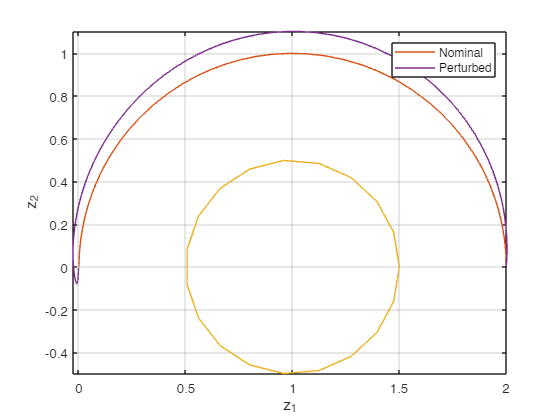

%Post-processing
x1 = xi1(:,1:3);
q1 = xi1(:,4:5);
hat_theta1 = xi1(:,6:7);
z1 = planar_traj(x1);
h = plot_planar_trajectory(z);
hold on
h(2) = plot_planar_trajectory(z1);
hold off
legend(h,{'Nominal','Perturbed'})

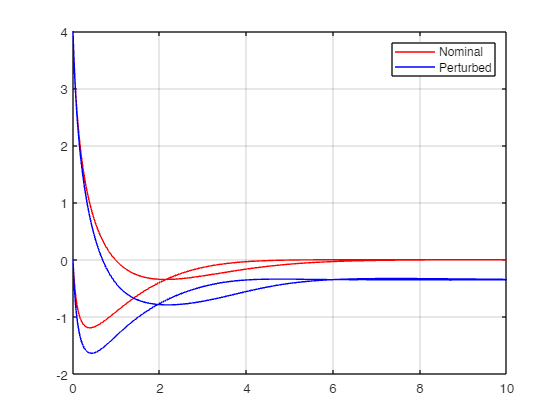

% Control inputs
u1 = cell2mat(arrayfun(@(I) kappa_1(x1(I,:)', xi1(I,4:7)'), (1:numel(t1)),'UniformOutput',false));
h = plot(t,u','r');
hold on
h2 = plot(t1,u1','b');
grid on
legend([h(1) h2(1)],{'Nominal','Perturbed'})
hold off

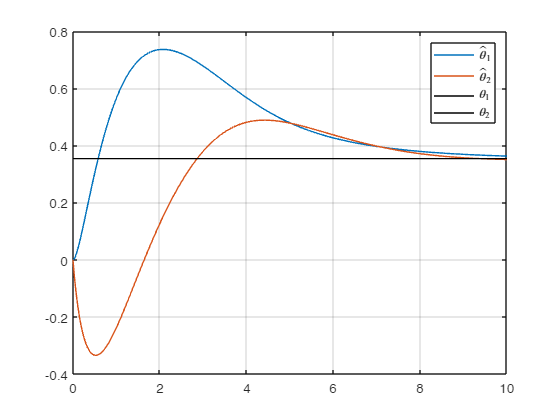

% Estimation error
h = plot(t1,hat_theta1);
grid on
h2 = line(get(gca,'xlim')'*ones(1,2),theta*ones(1,2),'color','k');
legend([h;h2],{'$\hat{\theta}_1$','$\hat{\theta}_2$','$\theta_1$','$\theta_2$'},'interpreter','latex')

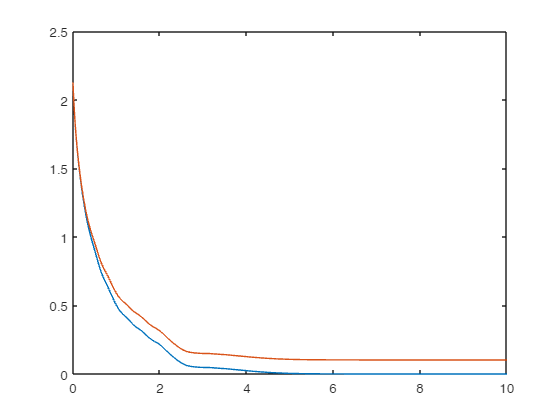

% Backstepping
u0 = kappa_1(psi(z_i),[q_i;hat_theta_i]);
V2_0 = V_2(xi_0(1:3),[q_i;hat_theta_i;u0],theta); %Lyapunov function (sanity check)
[t2,j2,xi2] = HyEQsolver(@F_cl2, @G_Omega2, @C_Omega2, @D_Omega2, [xi_0;hat_theta_i;u0;V2_0], TSPAN, JSPAN, rule);

V2_test = arrayfun(@(I) V_2( xi2(I,1:3)' , xi2(I,4:9)', theta ), (1:numel(t2))');
plot(t2, [V2_test, xi2(:,end)])

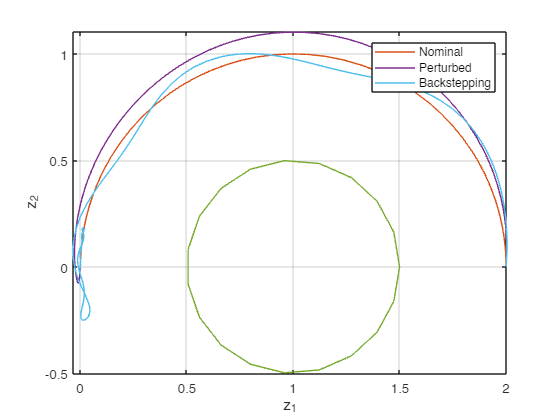

%Post-processing
x2 = xi2(:,1:3);
q2 = xi2(:,4:5);
hat_theta2 = xi2(:,6:7);
z2 = planar_traj(x2);
h = plot_planar_trajectory(z);
hold on
h(2) = plot_planar_trajectory(z1);
hold on
h(3) = plot_planar_trajectory(z2);
hold off
legend(h,{'Nominal','Perturbed','Backstepping'})

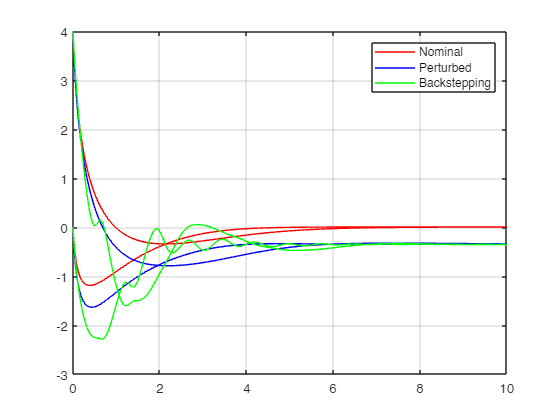

% Control inputs
u2 = xi2(:,8:9);
h = plot(t,u,'r');
hold on
h1 = plot(t1,u1','b');
h2 = plot(t2,u2,'g');
grid on
legend([h(1) h1(1) h2(1)],{'Nominal','Perturbed','Backstepping'})
hold off

## Tests

In this section, we run some tests to ensure that the computation of the derivatives is correct.

x0 = rand(3,1)*2-1;
z0 = rand(2,1)*2-1;
q0 = rand(2,1)*2-1;
q0 = q0/norm(q0);
vx =  rand(3,1)*2-1;
vz = rand(2,1)*2-1;
hat_theta0 = rand(2,1)*2-1;
xc1_0 = [q0;hat_theta0];
%[t,r1,r2] = test_derivatives(@psi_inv,@Dpsi_inv,x0,@(x) vx);
%[t,r1,r2] = test_derivatives(@psi,@Dpsi,z0, @(z) vz);
%[t,r1,r2] = test_derivatives(@(z) vec(Dpsi(z)),@DDpsi,z0, @(z) vz);
%[t,r1,r2] = test_derivatives(@(x) phi(x,q0) ,@(x) Dphi(x,q0),x0, @(x) vx);
%[t,r1,r2] = test_derivatives(@(q) phi(x0,q) ,@(q) Dqphi(x0,q),q0,@(q) [q(2);-q(1)]);
%[t,r1,r2] = test_derivatives(@(q) vec(Dphi(x0,q)) ,@(q) Dq_Dphi(x0,q),q0,@(q) [q(2);-q(1)]);
%[t,r1,r2] = test_derivatives(@(x) vec(Dphi(x,q0)) ,@(x) DDphi(x,q0),x0,@(x) vx);
%[t,r1,r2] = test_derivatives(@(q) kappa_0(x0,q) ,@(q) Dqkappa_0(x0,q),q0,@(q) [q(2);-q(1)]);
%[t,r1,r2] = test_derivatives(@(x) kappa_0(x,q0) ,@(x) Dxkappa_0(x,q0),x0,@(x) vx);
%[t,r1,r2] = test_derivatives(@(q) V_0(x0,q) ,@(q) DqV_0(x0,q),q0,@(q) [q(2);-q(1)]);
%[t,r1,r2] = test_derivatives(@(x) V_0(x,q0) ,@(x) DxV_0(x,q0),x0,@(x) vx);
%[t,r1,r2] = test_derivatives(@(q) kappa_1(x0,[q;hat_theta0]) ,@(q) Dqkappa_1(x0,[q;hat_theta0]),q0,@(q) [q(2);-q(1)]);
[t,r1,r2] = test_derivatives(@(x) kappa_1(x,xc1_0) ,@(x) Dxkappa_1(x,xc1_0),x0,@(x) vx);

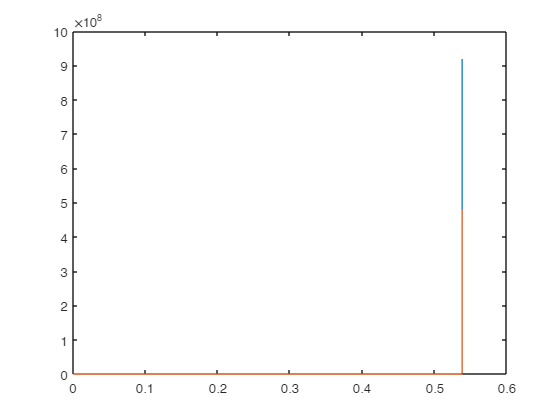

plot(t,abs(r1-r2))

## Problem Setup

We consider the problem of globally asymptotically stabilizing the origin for a vehicle moving on a plane with an obstacle represented by the following set:


$$\mathcal{N}:=z_0+r\overline{\mathbb{B}}$$


with $z_0\in\mathbb{R}^2$ and $r>0$ such that the origin is not contained in $\mathcal{N}$.

We consider that the evolution in time of the position $z\in\mathbb{R}^2\backslash\mathcal{N}$ of the vehicle is described by 


$$\dot{z}=u+\theta$$


where $u\in\mathbb{R}^2$ is the input and $\theta$ is an unknown constant that is known to belong to the set 


$$\Omega:=\{\theta\in\mathbb{R}^2:|\theta|\leq \theta_0\}$$


Since the function


$$\psi(z):=\left(\frac{z-z_0}{|z-z_0|},\log(|z-z_0|-r)\right)$$


is a diffeomorphism between $\mathbb{R}^2\backslash\mathcal{N}$ and $\mathcal{X}:=S^1\times \mathbb{R}$, we reformulate the problem as the stabilization of $\psi(0)$ for 


$$\dot{x}=F_{\theta}(x,q,u)=\mathcal{D}\psi(\psi^{-1}(x))(u+\theta)$$


where $\mathcal{D}\psi(\psi^{-1}(x))$ is the Jacobian matrix of $\psi$ evaluated at $\psi^{-1}(x)$.

The plant is then a control affine system of the form


$$\dot{x}=f(x,q)+H(x,q)u+W(x,q)\theta$$


with $f(x,q) = 0$ and $H(x,q) = W(x,q)= \mathcal{D}\psi(\psi^{-1}(x))$.

function x = psi(z)
    global z_0 r
    x = [(z-z_0)/norm(z-z_0);log(norm(z-z_0)-r)];
end

function out = Dpsi(z)
    global z_0 r
    out= [PT((z-z_0)/norm(z-z_0))/norm(z-z_0);1/(norm(z-z_0)-r)*(z-z_0)'/norm(z-z_0)];
end

function out = DDpsi(z)
    global z_0 r
    s = (z-z_0)/norm(z-z_0);
    aux = Dpsi(z);
    out1 = -s*s'/(norm(z-z_0)-r)^2+PT(s)/(norm(z-z_0)-r)/norm(z-z_0);
    out2 = -vec(PT(s))*(z-z_0)'./norm(z-z_0)^3-(kron(s,eye(2))+kron(eye(2),s))*aux(1:2,:)/norm(z-z_0);
    out = [out2(1:2,:);out1(1,:);out2(3:4,:);out1(2,:)];
end

function z = psi_inv(x)
    global z_0 r
    z = z_0+x(1:2)*(exp(x(3))+r);
end

function out = Dpsi_inv(x)
    global r
    out = [[1;0]*(exp(x(3))+r),[0;1]*(exp(x(3))+r),x(1:2)*exp(x(3))];
end

function out = PT(x)
    n = numel(x);
    out = eye(n)-x*x';
end

function out = f(x,q)
    out = zeros(3,1);
end

function out = H(x,q)
    out = Dpsi(psi_inv(x));
end

function out = W(x,q)
    out = Dpsi(psi_inv(x));
end

function dx = F(x,q,u,theta)
    dx = f(x,q) + H(x,q)*u + W(x,q)*theta;
end

## The Nominally Synergistic Controller

Let 


$$V_0(x,q):=\begin{cases}\frac{1}{2}|\phi_q(x)-\phi_q(\psi(0))|^2 & \text{ if }x\in U_q\\+\infty & \text{otherwise}\end{cases}$$


for each $(x,q)\in\mathcal{X}\times\mathcal{X}_c$, where $q\in\mathcal{X}_c:= \{q\in S^{1}: q^\top x_{12}^0\leq \gamma\}$ is the controller variable with continuous-time dynamics


$$\dot{q}=F_c(x,q):=-\Gamma(q)\Pi(q)\nabla_qV_0(x,q)$$


 for each$(x,q)\in\mathcal{X}\times\mathcal{X}_c$, $x_{12}^0$ is the shorthand notation for the first two components $\psi(0)$, $\gamma\in(-1,1)$ is a controller parameter, $\Gamma(q):= \max\{0,\gamma-q^\top x_{12}^0\}$, and 


$$\phi_q(x):=\left(\frac{q_2x_1-q_1x_2}{1-q_1x_1-q_2x_2},x_3\right)$$


for each $x:=(x_1,x_2,x_3)\in U_q:=\{x\in\mathcal{X}:q_1x_1+q_2x_2\neq 1\}$. Defining $D_c(x,q)=\mathcal{X}_c$ for each $(x,q)\in\mathcal{X}\times\mathcal{X}_c$ and


$$\kappa_0(x,q):=-(\mathcal{D}\psi(\psi^{-1}(x)))^\top\mathcal{D}\phi_q(x)^\top(\phi_q(x)-\phi_q(\psi(0)))$$


for each $(x,q)\in\text{dom}\,\kappa_0$, we show in the paper that the hybrid controller $(\kappa_0,V_0, D_c, F_c)$ is nominally synergistic relative to 


$$\mathcal{A}:=\{(x,q)\in\mathcal{X}\times\mathcal{X}_c:x=\psi(0)\}$$


with synergy gap exceeding $\delta$, for any positive function $\delta:\mathcal{X}\times\mathcal{X}_c\to\mathbb{R}_{>0}$.

function out = delta(x,q)
    out = 1;
end

function out = U(x,q)
    if q'*x(1:2) ~= 1
        out = 1;
    else
        out = 0;
    end
end

function out = phi(x,q)
    out = [(q(2)*x(1)-q(1)*x(2))/(1-q'*x(1:2)),x(3)]';
end

function out = Dqphi(x,q)
    d1 = -x(2)/(1-q'*x(1:2))+(q(2)*x(1)-q(1)*x(2))*x(1)/(1-q'*x(1:2))^2;
    d2 = x(1)/(1-q'*x(1:2))+(q(2)*x(1)-q(1)*x(2))*x(2)/(1-q'*x(1:2))^2;
    out = [d1 d2; 0 0];
end

function out = Dphi(x,q)
    out = zeros(2,3);
    out(2,3) = 1;
    out(1,1) = (q(2)-x(2))/(1-q'*x(1:2))^2;
    out(1,2) = -(q(1)-x(1))/(1-q'*x(1:2))^2;
end

function out = Dq_Dphi(x,q)
    out = zeros(6,2);
    out(1,1) = 2*(q(2)-x(2))*x(1)/(1-q'*x(1:2))^3;
    out(1,2) = (1-q'*x(1:2))^(-2)+2*(q(2)-x(2))*x(2)/(1-q'*x(1:2))^3;
    out(3,1) = -(1-q'*x(1:2))^(-2)-2*(q(1)-x(1))*x(1)/(1-q'*x(1:2))^3;
    out(3,2) = -2*(q(1)-x(1))*x(2)/(1-q'*x(1:2))^3;
end

function out = DDphi(x,q)
    out = zeros(6,3);
    out(1,1) = 2*q(1)*q(2)/(1-q'*x(1:2))^2+2*(q(2)*x(1)-q(1)*x(2))*q(1)^2/(1-q'*x(1:2))^3;
    out(1,2) = q(2)^2/(1-q'*x(1:2))^2-q(1)^2/(1-q'*x(1:2))^2+2*(q(2)*x(1)-q(1)*x(2))*q(1)*q(2)/(1-q'*x(1:2))^3;
    out(3,1) = out(1,2);
    out(3,2) = -2*q(1)*q(2)/(1-q'*x(1:2))^2+2*(q(2)*x(1)-q(1)*x(2))*q(2)^2/(1-q'*x(1:2))^3;
end

function out = V_0(x,q)
    if U(x,q)
        x0 = psi(zeros(2,1));
        out = 0.5*norm(phi(x,q)-phi(x0,q))^2;
    else
        out = Inf;
    end
end

function out =  DxV_0(x,q)
    out = (phi(x,q)-phi(psi(zeros(2,1)),q))'*Dphi(x,q);
end


function out = DqV_0(x,q)
    x0 = psi(zeros(2,1));
    out = (phi(x,q)-phi(x0,q))'*(Dqphi(x,q)-Dqphi(x0,q));
end

**Definition:** The derivative of a matrix-valued function of matrices $F:\mathbb{R}^{n\times q}\to\mathbb{R}^{m\times r}$ is given by


$$\mathcal{D} F(X)=\frac{\partial vec(F(X))}{\partial vec(X)^\top}$$


for each $X\in\mathbb{R}^{n\times q}$, where $vec(X)$ is an operator that stacks all the columns of $X$ into a single column so that $X_{ij}=[vec(X)]_{n\times (j-1)+i}$ for integers $1\leq i\leq n$ and $1\leq j \leq q$.

function out = Gamma(q)
    global gamma
    x0 = psi(zeros(2,1));
    out = max([0,gamma-x0(1:2)'*q]);
end

function dq = F_c(x,q)
    dq = -Gamma(q)*PT(q)*DqV_0(x,q)';
end

function out = kappa_0(x,q)
    global Gamma_0
    x0 = psi(zeros(2,1));
    out = -Gamma_0*Dpsi(psi_inv(x))'*Dphi(x,q)'*(phi(x,q)-phi(x0,q));
end

function out = Dqkappa_0(x,q)
    global Gamma_0
    out = -Gamma_0*Dpsi(psi_inv(x))'*( ...
        kron( (phi(x,q)-phi(psi(zeros(2,1)),q))' ,eye(3)) * K(2,3) * Dq_Dphi(x,q)...
        + Dphi(x,q)' * ( ...
            Dqphi(x,q) - Dqphi(psi(zeros(2,1)),q) ...
        ) ...
    );
end

function out = Dxkappa_0(x,q)
    global Gamma_0
    phi0 = phi(psi(zeros(2,1)),q);
    psi_u = Dpsi(psi_inv(x));
    DV = kron((phi(x,q)-phi0)',eye(3))*K(2,3)*DDphi(x,q)+Dphi(x,q)'*Dphi(x,q);
    Dpsi_u = DDpsi(psi_inv(x))*Dpsi_inv(x);
    out = -Gamma_0*(kron((phi(x,q)-phi0)'*Dphi(x,q),eye(2))*K(3,2)*Dpsi_u+psi_u'*DV);
end

As explained in Section IV, the minimum and the minimizer of $V_0$ as well as the synergy gap function $\mu_{V_0}$ are essential pieces in assembling the nominal synergistic controller. We implement these functions below.

function out = varrho_V0(x,q)
    global gamma
    x0 = psi(zeros(2,1));
    if x(1:2)'*x0(1:2) == -1
        %out = (randi(2)*2-3)*[x0(2);-x0(1)];
        out = [x0(2);-x0(1)]; % to ensure determinism
    else
        rho = -(x0(1:2)+x(1:2))/norm((x0(1:2)+x(1:2)));
        if rho'*x(2:3) > gamma
            out = gamma*x0(1:2)+sqrt(1-gamma^2)*PT(x(1:2))*rho;
        else
            out = rho;
        end
    end
end

function out = nu_V0(x,q)
    next_q = varrho_V0(x,q);
    out = V_0(x,next_q);
end

function out = mu_V0(x,q)
    out = V_0(x,q)-nu_V0(x,q);
end

The set $\mathcal{A}$ globally asymptotically stable when $\theta=0$ for the hybrid closed-loop system $\mathcal{H}_0:=(C_0,F_{cl,0},D_0,G_{cl,0})$ resulting from the interconnection between the plant and the nominal ynergistic controller $(\kappa_0,V_0, D_c, F_c)$. 

function dxi = F_cl0(xi)
    x = xi(1:3);
    q = xi(4:5);
    theta = zeros(2,1); % Since this is the nominal case
    dx = F(x,q,kappa_0(x,q),theta);
    dq = F_c(x,q);
    dxi = [dx;dq];
end

function out = C_0(xi)
    x = xi(1:3);
    q = xi(4:5);
    if mu_V0(x,q) <= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function out = D_0(xi)
    x = xi(1:3);
    q = xi(4:5);
    if mu_V0(x,q) >= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function next_xi = G_cl0(xi)
    x = xi(1:3);
    q = xi(4:5);
    next_xi = [x;varrho_V0(x,q)];
end

## Adaptive Backstepping of Synergistic Hybrid Feedback for Affine Control Systems

In this section, we modify the nominal synergistic controller $(\kappa_0,V_0, D_c, F_c)$ to address the case of nonzero disturbances, i.e., $\theta\neq0$, under the assumption that $\theta$ belongs to a known compact set

$\Omega:=\{\theta\in\mathbb{R}^2:|\theta|\leq \theta_0\}$.

In that direction, we add a controller state $\hat{\theta}$ with the continuous dynamics

$\dot{\hat\theta}= \Gamma_1\text{Proj}((\mathcal{D}\psi(\psi^{-1}(x)))^\top\nabla_x V_0(x,q),\hat{\theta})$,

where $\Gamma_1\in\mathbb{R}^{2\times 2}$ is a symmetric positive definite matrix and $\text{Proj}$ is the projection operator implemented below.

function out = Proj(eta, hat_theta)
    global  theta_0 epsilon
    ell = numel(eta);
    p = (hat_theta'*hat_theta-theta_0^2)/(epsilon^2+2*epsilon*theta_0);
    gradp = 2*hat_theta/(epsilon^2+2*epsilon*theta_0);
    if p<=0 || gradp'*eta<=0
        out = eta;
    else
        out = (eye(ell)-p*(gradp*gradp')/norm(gradp)^2)*eta;
    end
end

The first step towards a robust synergistic controller is to implement the synergistic controller $(\kappa_1,V_1,D_{c,1},F_{c,1})$ according to the guidelines given in Section VI. Note that, in the present example, Assumption 2 is satisfied with $\hat{W}(x,q)=I_2$.

function u = kappa_1(x,x_c1)
    global hat_W
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    u = kappa_0(x,q)-hat_W*hat_theta;
end

function out = Dxkappa_1(x,x_c1)
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    out = Dxkappa_0(x,q)-kron(hat_theta',eye(2))*Dx_hat_W(x,q);
end

function out = Dqkappa_1(x,x_c1)
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    out = Dqkappa_0(x,q)-kron(hat_theta',eye(2))*Dq_hat_W(x,q);
end

function out = Dx_hat_W(x,q)
    out = zeros(4,3); %hat_W = eye(2), so its derivative is 0
end
function out = Dq_hat_W(x,q)
    out = zeros(4,2); %hat_W = eye(2), so its derivative is 0
end

function out = V_1(x,x_c1,theta)
    global Gamma_1
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    out = V_0(x,q)+0.5*norm(Gamma_1^(-1/2)*(theta-hat_theta))^2;
end

function dx_c1 = F_c1(x,x_c1)
    global Gamma_1 
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    dq = F_c(x,q);
    dhat_theta = Gamma_1*Proj(Dpsi(psi_inv(x))'*DxV_0(x,q)',hat_theta);
    dx_c1 = [dq;dhat_theta];
end

Defining 


$$D_{c,1}:= D_{c}\times (\Omega+\epsilon\overline{\mathbb{B}})$$


we are able to compute the minimum and the minimizer of $V_1$ as well as the synergy gap function.

function out = nu_V1(x,x_c1,theta)
    q = x_c1(1:2);
    out = nu_V0(x,q);
end

function out = varrho_V1(x,x_c1,theta)
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    out = [varrho_V0(x,q);
        theta];
end

function out = mu_V1(x,x_c1,theta)
    global Gamma_1
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    out = mu_V0(x,q)+0.5*norm(Gamma_1^{-1/2}*(theta-hat_theta))^2;
end

The synergistic controller $(\kappa_1,V_1,D_{c,1},F_{c,1})$ cannot be implemented, because it depends on $\theta$, which is not known. To address this issue, we develop a robust synergistic controller, which is founded on the knowledge that $\theta$ belongs to the compact set $\Omega$ and requires the definition of a suitable jump map.

function out = min_mu_V1(x,x_c1)
    global theta_0
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    if norm(hat_theta) <= theta_0
        out = mu_V0(x,q);
    else
        % These computations assume Gamma_1 = eye(2)
        out = mu_V0(x,q)+0.5*(1-theta_0/norm(hat_theta))^2*norm(hat_theta)^2;
    end
end

function out = hat_G(hat_theta)
    global theta_0
    if norm(hat_theta) <= theta_0
        out = hat_theta;
    else
        out = theta_0*hat_theta/norm(hat_theta);
    end
end

function out = G_c1(x,x_c1)
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    out = [varrho_V0(x,q);
        hat_G(hat_theta)];
end

The hybrid closed-loop system $\mathcal{H}_1:=(C_{\Omega,1},F_{cl,1},D_{\Omega,1},G_{\Omega,1})$ is derived from the robust synergistic controller $(\kappa_1,\{V_{1,\theta}\}_{\theta\in\Omega},D_{c,1},F_{c,1},G_{c,1})$ and it is implemented below.

function out = C_Omega1(xi)
    x = xi(1:3);
    x_c1 = xi(4:7);
    q = x_c1(1:2);
    if min_mu_V1(x,x_c1) <= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function dxi = F_cl1(xi)
    global theta
    x = xi(1:3);
    x_c1 = xi(4:7);
    q = x_c1(1:2);
    dx = F(x,q,kappa_1(x,x_c1),theta);
    dx_c1 = F_c1(x,x_c1);
    dxi = [dx;dx_c1];
end

function out = D_Omega1(xi)
    x = xi(1:3);
    x_c1 = xi(4:7);
    q = x_c1(1:2);
    if min_mu_V1(x,x_c1) >= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function next_xi = G_Omega1(xi)
    x = xi(1:3);
    x_c1 = xi(4:7);
    next_x = x;
    next_x_c1 = G_c1(x,x_c1);
    next_xi = [next_x;
        next_x_c1];
end

For any $\theta\in\Omega$, the set 


$$\mathcal{A}_{1,\theta}:=\mathcal{A}\times\{\theta\}$$


is globally asymptotically stable for the hybrid closed-loop system $\mathcal{H}_1:=(C_{\Omega,1},F_{cl,1},D_{\Omega,1},G_{\Omega,1})$.

## Backstepping

Given a nominally synergistic controller $(\kappa_0,V_0,D_c,F_c)$, we extend the dynamics of the controller in Section VI.B to include the input $u$ as a controller state:


$$\dot{x}_{c,2}=F_{c,2}(x,x_{c,2})$$


with $x_{c,2}:=(x_{c,1},u)$ and $F_{c,2}$ implemented below.

function out = v(x,x_c2)
    global Gamma_2
    x_c1 = x_c2(1:4);
    q = x_c1(1:2);
    u = x_c2(5:6);
    out = W(x,q)'*(DxV_0(x,q)'-Dxkappa_1(x,x_c1)'*Gamma_2^(-1)*(u-kappa_1(x,x_c1)));
end

function out = f_u(x,x_c2)
    global Gamma_1 Gamma_2 k_u hat_W
    x_c1 = x_c2(1:4);
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    u = x_c2(5:6);
    out = -hat_W*Gamma_1*Proj(v(x,x_c2),hat_theta)-k_u*(u-kappa_1(x,x_c1))...
        -Gamma_2*H(x,q)'*DxV_0(x,q)'+Dxkappa_1(x,x_c1)*F(x,q,u,hat_theta);
end

function dx_c2 = F_c2(x,x_c2)
    global Gamma_1
    x_c1 = x_c2(1:4);
    q = x_c1(1:2);
    hat_theta = x_c1(3:4);
    u = x_c2(5:6);
    dx_c2 = [F_c(x,q);
        Gamma_1*Proj(v(x,x_c2),hat_theta);
        f_u(x,x_c2)+Dqkappa_1(x,x_c1)*F_c(x,q)];
end

The following set 


$$D_{c,2}(x,x_{c,2}):=\{(g_{c,1},g_u):g_{c,1}\in D_{c,1}(x,x_{c,1}), g_u=\kappa_1(x,g_{c,1})\}$$


constrains the values of the controller variables after a jump as specified by the jump map

$G_{c,2}(x,x_{c,2}):=\{(g_{c,1},g_u)\in D_{c,2}(x,x_{c,2}):g_{c,1}\in G_{c,1}(x,x_{c,1})\}$.

The missing piece of the robust synergistic controller after backstepping is the minimum of the synergy gap function:


$$\min_{\theta\in\Omega}\mu_{V_{2,\theta}}(x,x_{c,2})= \min_{\theta\in\Omega}\mu_{V_{1,\theta}}(x,x_{c,1})+\frac{1}{2}\left|\Gamma_2^{-\frac{1}{2}}(u-\kappa_1(x,x_{c,1})\right|^2$$


where $\Gamma_2\in\mathbb{R}^{2\times 2}$ is a symmetric positive definite matrix. These functions are implemented below.

function out = V_2(x,x_c2,theta)
    global Gamma_2
    x_c1 = x_c2(1:4);
    u = x_c2(5:6);
    out = V_1(x,x_c1,theta);
    if ~isinf(out)
        out = out+0.5*norm(Gamma_2^(-1/2)*(u-kappa_1(x,x_c1)))^2;
    end
end

function g_c2 = G_c2(x,x_c2)
    x_c1 = x_c2(1:4);
    g_c1 = G_c1(x,x_c1);
    g_u = kappa_1(x,g_c1);
    g_c2 = [g_c1;g_u];
end

function out = min_mu_V2(x,x_c2)
    global Gamma_2
    x_c1 = x_c2(1:4);
    u = x_c2(5:6);
    out = min_mu_V1(x,x_c1);
    if ~isinf(out)
        out = out+0.5*norm(Gamma_2^(-1/2)*(u-kappa_1(x,x_c1)))^2;
    end
end

The hybrid closed-loop system $\mathcal{H}_2:=(C_{\Omega,2},F_{cl,2},D_{\Omega,2},G_{\Omega,2})$ is derived from the robust synergistic controller $(\kappa_2,\{V_{2,\theta}\}_{\theta\in\Omega},D_{c,2},F_{c,2},G_{c,2})$ and it is implemented below.

function out = C_Omega2(xi)
    x = xi(1:3);
    x_c2 = xi(4:9);
    q = x_c2(1:2);
    if min_mu_V2(x,x_c2) <= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function dxi = F_cl2(xi)
    global theta Gamma_2 k_u
    x = xi(1:3);
    x_c2 = xi(4:9);
    x_c1 = x_c2(1:4);
    q = x_c2(1:2);
    hat_theta = x_c2(3:4);
    u = x_c2(5:6);
    dx = F(x,q,u,theta);
    dx_c2 = F_c2(x,x_c2);
    dV2 = DxV_0(x,q)*F(x,q,kappa_0(x,q),zeros(2,1))...
        -k_u*(u-kappa_1(x,x_c1))'*Gamma_2^(-1)*(u-kappa_1(x,x_c1));
    dxi = [dx;dx_c2;dV2];
end

function out = D_Omega2(xi)
    x = xi(1:3);
    x_c2 = xi(4:9);
    q = x_c2(1:2);
    if min_mu_V2(x,x_c2) >= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function next_xi = G_Omega2(xi)
    global theta
    x = xi(1:3);
    x_c2 = xi(4:9);
    next_x = x;
    next_x_c2 = G_c2(x,x_c2);
    next_xi = [next_x;next_x_c2;V_2(next_x,next_x_c2,theta)];
end


## Final Remarks

We found synergistic hybrid feedback to be useful in the stabilization and trajectory tracking for dynamical systems with rotational degrees of freedom that are subject to topological obstructions to stabilization with continuous feedback. You may find many of these applications in:

Casau, P., Cunha, R., Sanfelice, R. G., & Silvestre, C. (2019). Hybrid control for robust and global tracking on smooth manifolds. *IEEE Transactions on Automatic Control*, *65*(5), 1870–1885.

Feel free to reach out to P. Casau at pcasau@ua.pt if you would like to apply synergistic hybrid feedback elsewhere.

## Auxiliary Functions

function z = planar_traj(x)
% 
% z = PLANAR_TRAJ(x)
%  Returns the trajectory in x coordinates in the z-plane
%
    N = size(x,1);
    z = zeros(N,2);
    for I = 1:N
        z(I,:) = psi_inv(x(I,:)')';
    end
end

function h = plot_planar_trajectory(z)
    global z_0 r
    draw_circle('center',z_0,'radius',r);
    hold on
    h = plot(z(:,1),z(:,2));
    axis equal
    grid on
    xlabel('z_1')
    ylabel('z_2')
    hold off
end

function [t,r1,r2] = test_derivatives(fun,Dfun,xi0,v)
    TSPAN = [0 1];
    n = numel(xi0);
    options = odeset('AbsTol',1e-8,'RelTol',1e-8);
    [t,xi] = ode45(@(t,xi) [v(xi(1:n));Dfun(xi(1:n))*v(xi(1:n))],TSPAN,[xi0;fun(xi0)],options);
    r1 = xi(:,n+1:end);
    r2 = zeros(numel(fun(xi0)),numel(t));
    for I = 1:numel(t)
        r2(:,I) = fun(xi(I,1:n)');
    end
    r2 = r2';
end
    